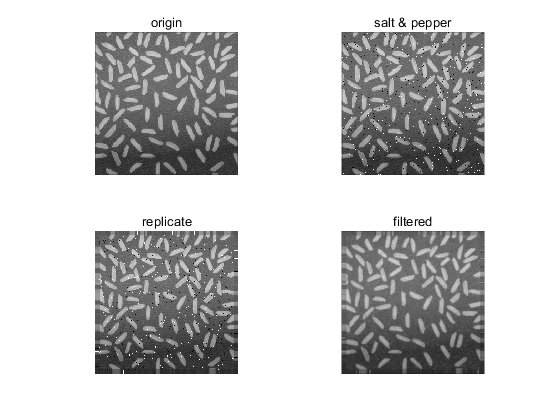

clc,clear,close all
I = imread('Fig2.tif');
subplot(2,2,1), imshow(I),title('origin');
J = imnoise(I,'salt & pepper',0.02);
subplot(2,2,2), imshow(J),title('salt & pepper');
% 首先对J进行边界填充
J15replicate = padarray(J,[15 15],'replicate');
subplot(2,2,3), imshow(J15replicate),title('replicate');
J15sliding = colfilt(J15replicate,[5 5],'sliding',@mean);
J15sliding=uint8(J15sliding);
subplot(2,2,4), imshow(J15sliding),title('filtered');

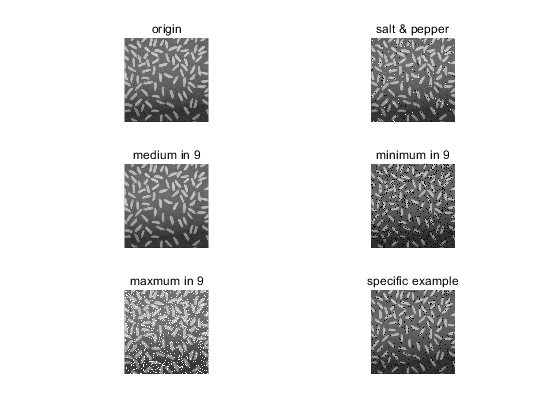

clc,clear,close all
I = imread('Fig2.tif');
title('origin')
subplot(3,2,1), imshow(I),title('origin');
J = imnoise(I,'salt & pepper',0.02);
subplot(3,2,2), imshow(J),title('salt & pepper');
B1 = ordfilt2(J,5,ones(3));
subplot(3,2,3), imshow(B1),title('medium in 9');
B2 = ordfilt2(J,1,ones(3));
subplot(3,2,4), imshow(B2),title('minimum in 9');
B3 = ordfilt2(J,9,ones(3));
subplot(3,2,5), imshow(B3),title('maxmum in 9');
B4 = ordfilt2(J,1,[0 1 0;1 0 1;0 1 0]);
subplot(3,2,6), imshow(B4),title('specific example');

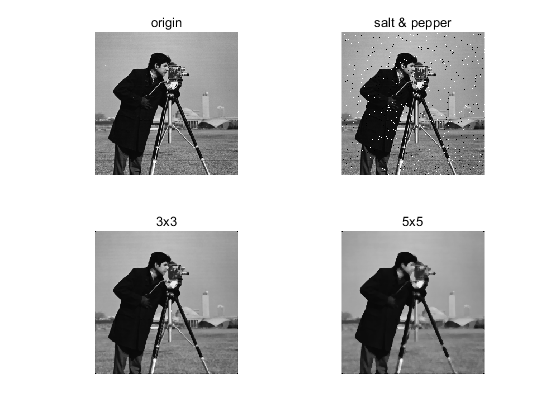

clc,clear,close all
I = imread('Fig0.tif');
title('origin')
subplot(2,2,1), imshow(I),title('origin');
J = imnoise(I,'salt & pepper',0.02);
subplot(2,2,2), imshow(J),title('salt & pepper');
B1 = ordfilt2(J,5,ones(3));
subplot(2,2,3), imshow(B1),title('3x3');
B2 = medfilt2(J,[5,5]);
subplot(2,2,4), imshow(B2),title('5x5');

clc,clear,close all
% 首先定义一个产生奇数维度的拉普拉斯矩阵的函数
w1 = genLaplacian(3)

w1 =      1     1     1
     1    -8     1
     1     1     1


w2 = genLaplacian(5)

w2 =      1     1     1     1     1
     1     1     1     1     1
     1     1   -24     1     1
     1     1     1     1     1
     1     1     1     1     1


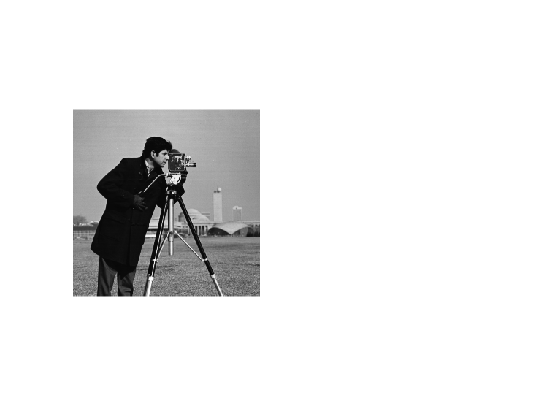

w3 = genLaplacian(9);
w4 = genLaplacian(15);
w5 = genLaplacian(25);
figure(1)
I = imread('Fig0.tif');
subplot(1,2,1), imshow(I);

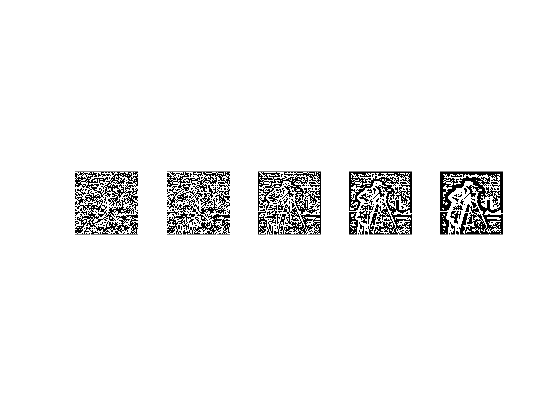

I = double(I);
figure(2)
C1 = conv2(I,w1,'same');
C2 = conv2(I,w2,'same');
C3 = conv2(I,w3,'same');
C4 = conv2(I,w4,'same');
C5 = conv2(I,w5,'same');
subplot(1,5,1),imshow(C1)
subplot(1,5,2),imshow(C2)
subplot(1,5,3),imshow(C3)
subplot(1,5,4),imshow(C4)
subplot(1,5,5),imshow(C5)

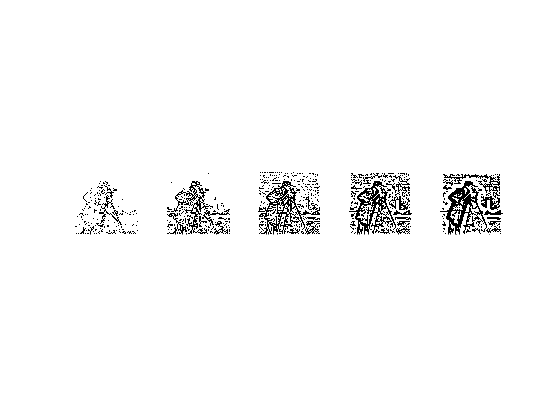

figure(3)
C1 = I - C1;
C2 = I - C2;
C3 = I - C3;
C4 = I - C4;
C5 = I - C5;
subplot(1,5,1),imshow(C1)
subplot(1,5,2),imshow(C2)
subplot(1,5,3),imshow(C3)
subplot(1,5,4),imshow(C4)
subplot(1,5,5),imshow(C5)

clc,clear,close all
I = imread('Fig0.tif');
H = fspecial('laplacian')

H =     0.1667    0.6667    0.1667
    0.6667   -3.3333    0.6667
    0.1667    0.6667    0.1667


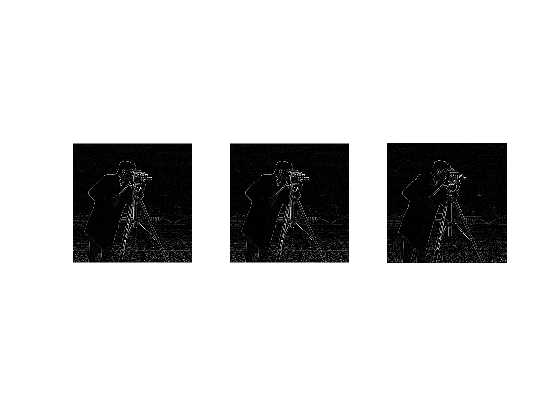

filtered1 = imfilter(I,H,'symmetric','conv');
filtered2 = imfilter(I,H,'replicate','conv');
filtered3 = imfilter(I,H,'circular','conv');
subplot(1,3,1),imshow(filtered1)
subplot(1,3,2),imshow(filtered2)
subplot(1,3,3),imshow(filtered3)

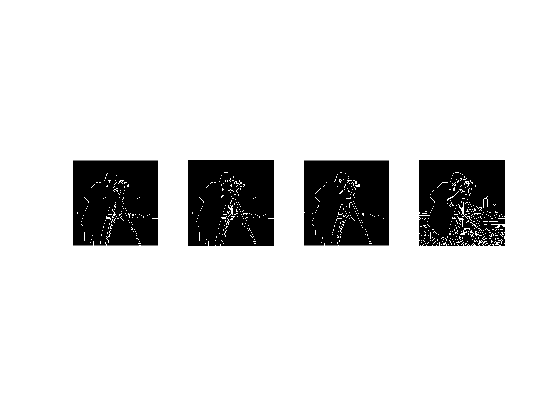

clc,clear,close all
I = imread('Fig0.tif');
edge1 = edge(I,'Sobel');
edge2 = edge(I,'Prewitt');
edge3 = edge(I,'Roberts');
edge4 = edge(I,'Canny');
subplot(1,4,1),imshow(edge1)
subplot(1,4,2),imshow(edge2)
subplot(1,4,3),imshow(edge3)
subplot(1,4,4),imshow(edge4)

function w = genLaplacian(n)
    w = ones(n);
    for i = 1:n
        for j = 1:n
            if(i == fix(n/2) + 1 && j == fix(n/2) + 1)
                w(i,j) = 1 - n*n;
            end
        end
    end
end